# Part 3: Further explore and visualize `penguins` 

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

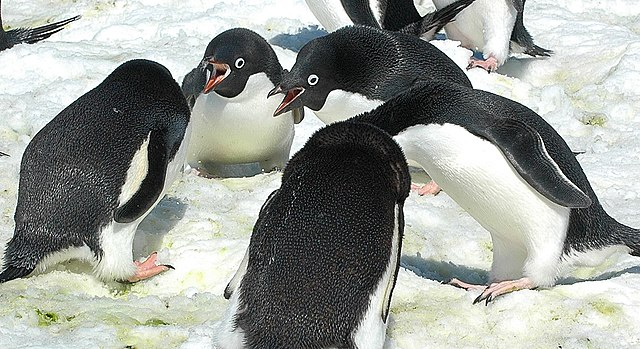

Adelie penguins having a group [meeting](https://commons.wikimedia.org/wiki/File:2007_Snow-Hill-Island_Luyten-De-Hauwere-Adelie-Penguin-19.jpg). 

In the biosciences data module***(add link to module 2 Github)***, we spent some time visualizing our penguin dataset. We'll start by returning to a few visualizations here. Make sure you've already gone through the [loading and cleaning data live script](matlab: edit S2_Load_clean_data.mlx). If you've previously gone through this script, but `penguins` is no longer in your workspace, this block of code will add `penguins` to your workspace and clean it up: 

filename = "penguins.csv";
penguins = readtable(filename);
penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);
penguins1 = rmmissing(penguins);

## Visualize the distribution of your data

It's always important to see how your data is distributed. For example, it might be spread out or it might be tightly clustered around a small range of values. If you measured the height of every person in the human population, you'd have a wide spread of heights, but if you only measured the heights of a group of babies all of the same age, your data would still vary, but it would be much more tightly clustered between a few values. We can use a [histogram](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) to visualize the spread of our data. A histogram plots the values of the variable we are plotting on the x-axis and the frequency with which each of those values appears in the data set on the y-axis. 

  Select different variables from `penguins1` in the drop-down below (change the value of `X`)  so you can look at the distribution or spread of the data for each penguin descriptor variable. 

% Create histogram of selected data
h1 = histogram(penguins1.flipper_length_mm,"DisplayStyle","bar","DisplayName","flipper_length_mm");
xlabel("Variable selected")
ylabel("Frequency")

 Adjust the data in the histogram to visualize different distributions and answer the following questions: 

- How would you describe the ***skew*** of the body mass histogram (is it pushed more to the left or right)?

- What is the ***range*** of the body mass histogram (what are the approximate minimum and maximum weight values in the population)?

- How would you describe the ***shape*** of the flipper length distribution (how many peaks do you see)?

- What is the ***range*** of the flipper length distribution? 

You can see that there are different types of distributions of this data. For example, it looks like the body mass histogram is skewed towards lower values (the left). It looks like bill length and flipper length are both [bimodal](https://en.wikipedia.org/wiki/Multimodal_distribution) distributions, where there are peaks at 2 different places in the histogram (one on the lower end of length, and one on the higher end). You might be wondering why this is happening-- does this depend on the species? (Great question!) 

## Separate data by species

We can separate the data by species as we did in the biosciences data module***(add link to module 2 Github)***, and plot the histogram for each species overlapping with each other to see what's going on. 

To separate data by species, we first find the rows of the table that correspond to a species name and then index the table by those rows, making sure to include all columns. This can be done in one line of code: 

gentoo = penguins1(penguins1.species == "Gentoo",:); 

Here, we made a new table called `gentoo` of just penguins of the Gentoo species.

Let's do the same so that we have one table for each species. 

  Create a table for Adelie penguins by filling in the blank below, uncommenting the line (remove % from the beginning), and running this section:

%adelie = penguins1(  == "Adelie",:);

***Tip:*** If compressing into one line of code feels like too much, you can also do it in two: 

###  Exercise 1: Create a table for Chinstrap penguins. 

Finally, create a table for the Chinstrap penguins here, named `chinstrap`: 

Awesome! We've created three new variables: `gentoo`, `adelie`, and `chinstrap`, which are each tables containing all the data for an individual species. Let's plot the histograms for flipper length broken up by individual species. 

Start with the histogram for just Gentoo penguins. Use the built-in function [`histogram()`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html). 

histogram(gentoo.flipper_length_mm)
xlabel("Flipper length (mm)")
ylabel("Frequency of length in Gentoo population")
title("Gentoo penguins flipper length")

Refer back to your answers to the questions about the full population histograms. Just looking at the gentoo penguin histogram, we see a smaller spread of the data (it goes from about 205-230 mm in length) than we see for the flipper length of all penguins (170-230 mm). So the gentoo penguins tend to have flipper lengths in the upper end of the initial histogram! This begins to get at our initial suspicion that the flipper length distribution may be bimodal and have multiple peaks due to species differences. Let's confirm by plotting all the histograms at once. 

Try running this and check out the overlapped histogram: 

h(1) = histogram(gentoo.flipper_length_mm, "FaceAlpha",0.5, SeriesIndex=1);
hold on
h(2) = histogram(chinstrap.flipper_length_mm, "FaceAlpha",0.5, SeriesIndex=2);
h(3) = histogram(adelie.flipper_length_mm, "FaceAlpha",0.5, SeriesIndex=4);
hold off 
xlabel("Flipper length (mm)")
ylabel("Frequency")
legend(h,"Gentoo", "Chinstrap", "Adelie")

*If you get an error running this code, make sure you've completed exercises 1 and 2- you should have variables named *`adelie`*, *`chinstrap`*, and *`gentoo`* in your workspace. *

There are a few new things going on in this chunk of code: 

1- The [`hold on`](https://www.mathworks.com/help/matlab/ref/hold.html)/`hold off` functions. These allow you to add new plots to an exisiting set of axes, which allows for plotting overlap. 

2- I've saved the histogram as an [object](https://www.mathworks.com/help/matlab/graphics-object-properties.html) `h`. You can see it in the workspace. This allows us to manipulate the histogram, add a legend, etc. You'll see that when I use the [`legend()` ](https://www.mathworks.com/help/matlab/ref/legend.html)function at the end to add descriptive labels to our histogram, the first input is the plot handle `h.`

3- Color! When you're writing up the results of a study, it's usually really helpful to pick a color to represent each part of a data set (in this case, each species) and stick with it. This way, when someone is reading your paper they have a more intuitive understanding of what's going on as they move through. The [`histogram()`](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html) function has several options you can add. One option is to utilize the "Series Index". Objects with the same series index value will use the same color. For example, you can always set Gentoo penguins to Series Index 1, which is the color blue by default. There is a default set of colors, or color order that is set by MATLAB® and is meant to be easily visible within the version you're using (i.e. dark mode). You can also hard code the colors by using the option "FaceColor" and then giving an input like "b" (blue) or "m" (magenta). I also used the option "FaceAlpha", which is a number from 0 to 1 and changes the transparency of the bars you are plotting. This allows you to look at where the overlap in your histograms occurs. 

  Try changing the alpha value and see what happens. You can also try changing the variable you're plotting (***Hint:*** try `gentoo.bodymass_g`, but make sure you're comparing the same variable type across all species). 

In the field, you would often want to compare species in this way. 

##  Exercise 2: Plot the body mass distribution yourself 

First, let's make the histogram (this histogram object is called `w`) for Gentoo body mass: 

figure()
w(1) = histogram (gentoo.body_mass_g, "FaceAlpha",0.5, SeriesIndex=1);
hold on

**A: Plot the histogram for Chinstrap body mass yourself, using Series Index 2 for color, with 0.5 transparency: **

**B: Do the same for Adelie body mass, with Series Index 4 for color and 0.5 transparency.**

**C: Turn the plotting hold off. **

**D: Add x and y labels to your chart, as well as a relevant title. **

**E:  Add a labeled legend for clarity! **

 This body mass difference turns out to be important for Gentoo penguins ecologically. Because they have larger body masses, they can dive deeper into the water (see [this article in Scientific American](https://www.scientificamerican.com/article/gentoo-penguins-thrive-while-adelies-and-chinstraps-falter-in-a-climate-changed-world/)) and their diet is, therefore, more varied than Adelie and Chinstrap penguins. Krill is the main food source of all 3 penguin species, and climate change has been leading to a decrease in available krill. Because Gentoo penguins have a more varied diet than Chinstrap and Adelie penguins, they have still been able to flourish despite a lack of krill. As a result, Gentoo penguins are rising in population, whereas Adelie and Chinstrap penguins are declining in population. 

This is a good example of how looking at a data distribution can help make sense of ecological phenomena. 

## Visualize data by using a box plot 

Another way to look at the distribution of your data is a [box plot](https://www.mathworks.com/help/stats/boxplot.html). 

Run: 

figure()
boxplot(penguins1.flipper_length_mm)
ylabel("Flipper Length (mm)")

You'll notice that now, the values of flipper length are along the y-axis. The red line represents the median (which we can consider the 50% percentile or midpoint) of the data set, where the bottom and top edges of the box represent the 25th and 75th percentiles of the data (the midpoint of the lower and upper half of the dataset, respectively). This is also called a box-and-whisker plot, because of the 'whiskers' that extend out of the box which represents the most extreme values in the dataset (that aren't considered so extreme that they are outliers). 

This way of looking at and describing data is called [**descriptive statistics **](https://en.wikipedia.org/wiki/Descriptive_statistics) and is the topic of the next script. 

## Exercise Answers

Exercise 1:

chinstrap = penguins1(penguins1.species == "Chinstrap",:);

  Exercise 2:

figure()
w(1) = histogram(gentoo.body_mass_g, "FaceAlpha",0.5,SeriesIndex=1);
hold on

w(2) = histogram(chinstrap.body_mass_g, "FaceAlpha",0.5, SeriesIndex=2); % A 
w(3) = histogram(adelie.body_mass_g, "FaceAlpha",0.5, SeriesIndex=4);   % B 
hold off % C
xlabel("Body Mass (g)") %D
ylabel("Frequency")
title("Body Mass distribution, all penguins")
legend(w,"Gentoo", "Chinstrap", "Adelie") %E

[*Continue to next section (Descriptive statistics)*](matlab: edit S4_Descriptive_stats.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)